Class - April 5th, 2023

First, we define a LTI system in state space representation:

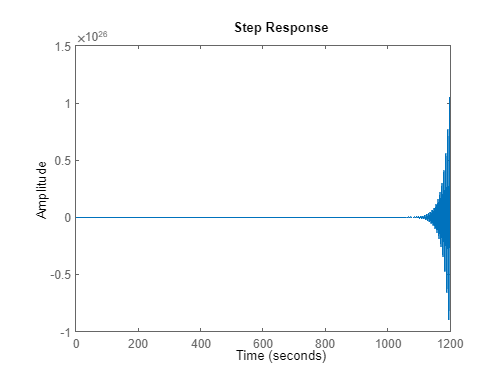

clear all; close all;
num = 1;
%den = [1 0.1 1]; % STABLE CASE
den = [1 -0.1 1]; % UNSTABLE CASE
[A,B,C,D] = tf2ss(num,den);
G = ss(A,B,C,D);
step(G)

Lyapunov Stability - Controller Synthesis:

[rowB colB] = size(B)

rowB = 2

colB = 1


Q = sdpvar(length(A));
Y = sdpvar(colB,rowB);

sdisplay(Q);
sdisplay(Y);

LMI1 = [Q*A'+A*Q+Y'*B'+B*Y<=0];
LMI2 = [Q>=0];

LMI = [LMI1,LMI2];

optimize(LMI)

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 5, order n = 5, dim = 9, blocks = 3
nnz(A) = 11 + 0, nnz(ADA) = 25, nnz(L) = 15
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.80E+00 0.000
  1 :   0.00E+00 4.45E-01 0.000 0.0454 0.9900 0.9900   1.00  1  0  2.7E-01
  2 :   0.00E+00 4.31E-02 0.000 0.0967 0.9900 0.9900   1.00  1  1  2.6E-02
  3 :   0.00E+00 3.92E-03 0.000 0.0911 0.9900 0.9900   1.00  1  1  2.4E-03
  4 :   0.00E+00 3.51E-04 0.000 0.0896 0.9900 0.9900   1.00  1  1  2.2E-04
  5 :   0.00E+00 3.11E-05 0.000 0.0885 0.9900 0.9900   1.00  1  1  1.9E-05
  6 :   0.00E+00 2.72E-06 0.000 0.0875 0.9900 0.9900   1.00  1  1  1.7E-06
  7 :   0.00E+00 2.35E-07 0.000 0.0865 0.9900 0.9900   1.00  1  1  1.4E-07
  8 :   0.00E+00 2.01E-08 0.000 0.0855 0.9900 0.9900   1.00  1  1  1.2E-08
  9 :   0.00E+00 1.70E-09 0.000 0.0846 0.9900 0.9900   1.00  1  1  1.0E-09
 10 :   0.00E+00 1.

ans = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.14.0.2206163 (R2023a)'
       yalmiptime: 1.1027
       solvertime: 0.6493
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0



Qs = value(Q);
Ys = value(Y);

K = Ys*inv(Qs);

Checking if the K is stabilizing the system:

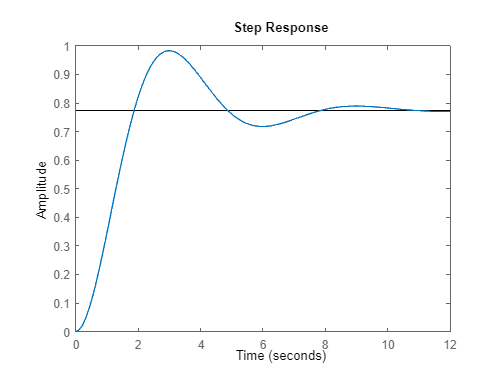

Gmf = ss(A+B*K,B,C+D*K,D);
step(Gmf)